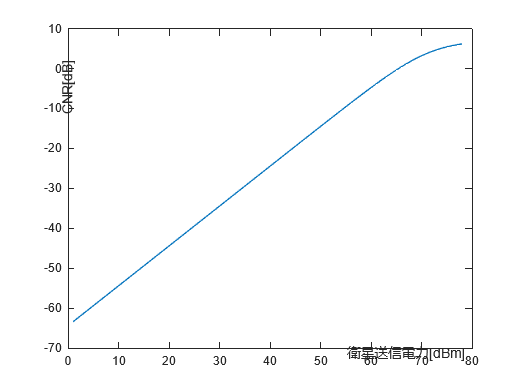

%衛星送信アンテナ
for PtdBm = 1:1:78

    PtW = 10 .^(PtdBm / 10) / 1000;
    GtoSCNR = 4.8283;
    SNoiseW = PtW / GtoSCNR; %送信電力中のノイズ電力[W]
    SNoisedBW = 10 * log10(SNoiseW);
    PtWnoise = PtW*((GtoSCNR - 1)/ GtoSCNR); %受信電力からノイズ分引いたやつ[W]
    PtdBmnoise = 10 * log10(PtWnoise * 1000);
    NFdBS= 10;
    fHz = 2.52* 10^9; 
    bw=5e6;
    lamdam = 3.0*(10^8) / fHz;
    dm = 1000 * 1000;
    GtdBi = 0;
    
    %地上受信アンテナ
    NFdBG = 10;
    GrdBi = 0;
    Gr = 10^(GrdBi / 10);
    
    %自由空間伝搬損失
    L = (4*pi*dm/ lamdam) ^ 2;
    LdB = 10*log10(L);
    LosdB = 20* log10(dm) + 20*log10(fHz) -147.6;
    
    
    TempK = 300;
    k = 1.38e-23;
    GNoiseW = k * TempK * bw * NFdBG;
    NoiseW = GNoiseW + 10 ^((SNoisedBW - LdB) / 10);
    NoisedBW = 10 * log10(NoiseW);
       
    %受信信号電力
    PdBm = PtdBmnoise + GtdBi - LdB + GrdBi;
    PW = 10 ^ (PdBm / 10) / 1000;
    CNR(PtdBm) = (PW) ./ (NoiseW);
    CNRdB(PtdBm) = 10 .* log10(CNR(PtdBm));

end

 plot(CNRdB)
 xlabel("衛星送信電力[dBm]")
 ylabel("CNR[dB]")